Load dataset

data = readmatrix('C:\Users\yashw_d6scpoj\Desktop\S2\MFC2\smoted_dataset1.csv');  % Replace with your file path
X = data(:, 1:end-1);  % Features
y = data(:, end);      % Target (labels 0,1,2)

% Add bias term (column of 1s)
X = [ones(size(X,1),1), X];

Split into training and testing

cv = cvpartition(size(X,1), 'HoldOut', 0.3);
X_train = X(training(cv), :);
y_train = y(training(cv));
X_test = X(test(cv), :);
y_test = y(test(cv));

% Number of classes
num_classes = length(unique(y_train));


One-hot encoding for training and testing labels

y_train_onehot = zeros(length(y_train), num_classes);
for i = 1:length(y_train)
    y_train_onehot(i, y_train(i) + 1) = 1;  % MATLAB index starts at 1
end


y_test_onehot = zeros(length(y_test), num_classes);
for i = 1:length(y_test)
    y_test_onehot(i, y_test(i) + 1) = 1;
end

% Setup
scores = zeros(size(X_test, 1), num_classes);

One-vs-All classification

for i = 1:num_classes
    % Binary target: 1 for this class, 0 for others
    y_binary = y_train_onehot(:, i);
    
    % Solve using pseudo-inverse: w = X^+ * y_binary
    w = pinv(X_train) * y_binary;
    
    % Score = X_test * w
    scores(:, i) = X_test * w;
end

Final predictions: choose class with highest score

[~, idx] = max(scores, [], 2);
y_pred = idx - 1;  % Adjust back to the original label range (0-based)

Evaluation

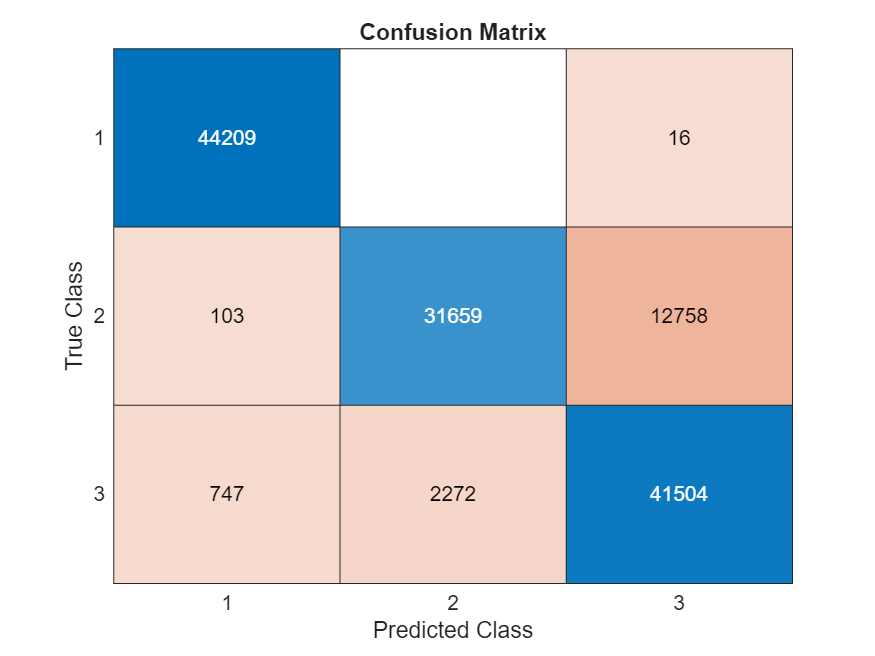

% Visualize confusion matrix
figure;
confusionchart(confMat);
title('Confusion Matrix');


% Accuracy
accuracy = mean(y_test == y_pred);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 88.07%
